x0 =  [100e9; 60e7; 11];

funciton

fun = @(x) misfit_sig(x, epsilon_exp, t, beam, dsigma);

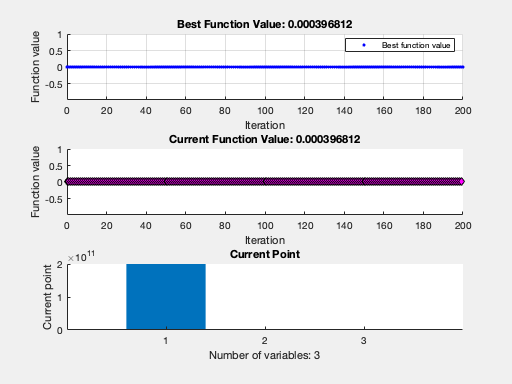

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


% Set nondefault solver options
options = optimoptions("surrogateopt","PlotFcn",["optimplotfvalconstr",...
    "optimplotfval","optimplotx"]);

% Solve
[solution,objectiveValue] = surrogateopt(fun,lb,ub,[],[],[],[],[],options);


% Clear variables
clearvars options